%% Setup
clear all
close all
clc

warning off;

cd /Users/rogerchen/Documents/MATLAB/rc_thesis_irf/Emp_App/RZ_Active_Rep/

%% Input Specs
timesample=1; % 2 means 1889-2015; 2 means post WWII
statechoice=1;  % 1 means default unemp threshold; 2 means default ZLB threshold
shockchoice=1; % 1 means news shock; 2 means BP shock
transformation=1; % 1 means Gordon-Krenn; 2 means Hall-Barro-Redlick
taxchoice=0; %0 means no taxes as control; 1 means ad taxy as a control
datafirstdiff=0; % means to difference the key GDP / Gov Spending series 

trend=0; %4 means quartic; 2 means quadratic; 0 means no trend  
nlag=4;% number of lags of control variables
opt=0; % 0 means Newey-West with bandwidth=i; 1 means optimal bandwidth (takes much longer to run)'

if transformation==1
    disp('Gordon-Krenn')
elseif transformation==2
    disp('Hall-Barro-Redlick')
end

Gordon-Krenn



if shockchoice==1
    disp('News shock')
elseif shockchoice==2
    disp('BP shock')
end

News shock



hor=20; % horizon for IRFs
clevel= 1.96; % confidence level % 1.96  1.64;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
run('figure_irfs_multipliers_setup.m')

ans = 0.3584

## Estimate VARs separately via MATLAB var

% split data into two subsamples
y_high = y_tvar(fu==1, :);
y_low = y_tvar(fu==0, :);
nlag = 4; p = nlag;
nvar = size(y_high, 2);

% estimate reduced form VARs and check stability
% high
Mdl_high = estimate_var(y_high, p);
companion_matrix = Mdl_high.AR{1};
for i=2:nlag
    companion_matrix = [companion_matrix, Mdl_high.AR{i}];
end
companion_matrix = [companion_matrix; [eye((nlag-1)*nvar, (nlag-1)*nvar), zeros((nlag-1)*nvar,nvar)]];
eigenvalues = eig(companion_matrix);
if any(abs(eigenvalues) >= 1)
    disp('Warning: The model may be unstable. Some roots are on or outside the unit circle.');
end

% low
Mdl_low = estimate_var(y_low, p);

companion_matrix = Mdl_high.AR{1};
for i=2:nlag
    companion_matrix = [companion_matrix, Mdl_high.AR{i}];
end
companion_matrix = [companion_matrix; [eye((nlag-1)*nvar, (nlag-1)*nvar), zeros((nlag-1)*nvar,nvar)]];
eigenvalues = eig(companion_matrix);
if any(abs(eigenvalues) >= 1)
    disp('Warning: The model may be unstable. Some roots are on or outside the unit circle.');
end

% compute the model high and model low coefficient matrices
Mdl_high_beta = Mdl_high.Constant; % initialise
Mdl_low_beta = Mdl_low.Constant; % initialise
for i=1:nlag
    Mdl_high_beta = [Mdl_high_beta, Mdl_high.AR{i}];
    Mdl_low_beta = [Mdl_low_beta, Mdl_low.AR{i}];
end

% look at the VAR coeffients and compare
Mdl_high_beta' % individually estimated high unemployment coefficients

ans =     0.0433    0.0046    0.0415
   -0.0986    0.1558    0.0459
    0.9623    0.8370    0.1045
    0.1954    0.0203    1.1133
    0.4100    0.1698    0.0604
   -0.8271   -0.3429   -0.1373
   -0.1250    0.0016   -0.1755
   -0.0742   -0.2266   -0.1531
    0.1887    0.4350    0.0085
    0.1005   -0.0365    0.0418


high_ind_beta = [1, 2:(2+11)]; % full TVAR estimation - indices of high unemployment coefficients within \beta

### Generate BS dependent variable using two subset regression coefficients

First, generate the two-subset-based residuals

y_tvar; % y vector
p = nlag

p = 4

lagy_tvar = lagmatrix(y_tvar, [1:p]); % lagged y that ends up being used to create fitted y -> residuals
Y = y_tvar(p+1:end,:);
lagY = lagy_tvar(p+1:end,:);
fu_trunc = fu(p+1:end);
[T,k] = size(Y);
X = [ones(T,1) lagY]

X =     1.0000         0    0.0572    1.0373    0.0010    0.0518    1.0342         0    0.0459    1.0315         0    0.0487    1.0474
    1.0000         0    0.0568    1.0493         0    0.0572    1.0373    0.0010    0.0518    1.0342         0    0.0459    1.0315
    1.0000         0    0.0537    1.0356         0    0.0568    1.0493         0    0.0572    1.0373    0.0010    0.0518    1.0342
    1.0000         0    0.0609    1.0342         0    0.0537    1.0356         0    0.0568    1.0493         0    0.0572    1.0373
    1.0000         0    0.0458    1.0925         0    0.0609    1.0342         0    0.0537    1.0356         0    0.0568    1.0493
    1.0000         0    0.0524    1.0892         0    0.0458    1.0925         0    0.0609    1.0342         0    0.0537    1.0356
    1.0000         0    0.0541    1.0693         0    0.0524    1.0892         0    0.0458    1.0925         0    0.0609    1.0342
    1.0000         0    0.0580    1.0363         0    0.0541    1.0693         

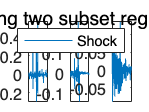


fitted_y_tvar = zeros(T,k);
for i=1:T
    fitted_y_tvar(i,:) = X(i,:)*(fu(i).*Mdl_high_beta') + X(i,:)*((1-fu(i)).*Mdl_low_beta');
end
resid = Y - fitted_y_tvar;

figure;
for i=1:3
    subplot(1,3,i);
    plot(resid(:,i));
end
legend('Shock', 'Gov Spend', 'GDP')
sgtitle('Residuals from using two subset regression coefficients')

Then compute the bootstrap dependent variable

y = y_tvar;
[T, k] = size(y_tvar);
TT = T-p % truncated time variable to match truncated fu, resid, Y etc.

TT = 501

I = fu(p+1:end);

B = 5;
horizon = 20;
bs_dv = zeros(TT, 3, B);
bs_irfa = zeros(B, 2, horizon);
bs_irfb = zeros(B, 2, horizon);
bs_irfa_ci = zeros(B, 2, horizon);
bs_irfb_ci = zeros(B, 2, horizon);
bs_pvala = zeros(2, horizon);
bs_pvalb = zeros(2, horizon);
lambda = 0.5;

% resid = resid - mean(resid);
for b=1:B
    y_bs = zeros(TT, 3);
    y_bs(1:p, :) = Y(1:p, :); % initialise the first p rows of the bootstrap dependent variable vector with the observed y
    resid_sample = datasample(resid, TT, 'Replace', true);
    
    for j=p+1:TT
        % define our starting params
        ind = I(j);
        % generate VAR terms
        plagy = [];
        for l=1:p
            plagy = [plagy, y_bs(j-l, :)];
        end
        x_bs = [1, plagy];
        res = [resid(j, 1), resid_sample(j, 2:3)];
        y_bs(j,:) = x_bs*(I(j).*Mdl_high_beta') + x_bs*((1-I(j)).*Mdl_low_beta')+ res;
    end
    bs_dv(:,:,b) = y_bs;

    % compute state-dependent LP irfs
    shock = y_bs(:,1);
    x=[constant, (1-I).*constant, I.*shock, (1-I).*shock, repmat(I,1,size(y_bs,2)).*y_bs, repmat((1-I),1,size(y_bs,2)).*y_bs];
    rpost=3;
    [irfa_lp, irfb_lp, ~, ~, ~, ~, ~, ~]=statelp(data,x,horizon,rpost,transformation, clevel, opt, 0, 0, p, 0); 
    
    % compute SVAR irfs
    y_high = y_bs(I==1,:);
    y_low = y_bs(I==0,:);
    [irfa_svar, irfb_svar, ~, ~] = stateSVAR(y_high, y_low, p, horizon);

    % get final model averaged irfs and store
    bs_irfa(b,:,:) = lambda * irfa_lp + (1-lambda)*irfa_svar;
    bs_irfb(b,:,:) = lambda * irfb_lp + (1-lambda)*irfb_svar;
end

% close all
% figure;
% hold on
% plot_series = 1
% plot(y(p+1:end, plot_series), 'Color', 'blue');
% for i=1:B
%     plot(bs_dv(:,plot_series,i), 'Color', 'red', 'LineWidth', 0.1);
% end
% title('Bootstrap (red) vs original (blue) time series - GDP')

Compute bootstrap p-values

Rewrite all of the above into a state dependent VAR/LP average IRF function with bootstrapped p-values

% compute the non-linear averaged estimator + for the model averaged forecast
if trend==4 % allow quartic trend
    x=[t', tsq', tcu', tqu', constant, (1-fu).*constant, fu.*shock, (1-fu).*shock, repmat(fu,1,size(x,2)).*x, repmat((1-fu),1,size(x,2)).*x];
    rpost=7; 
elseif trend==2 % allow quadratic trend
    x=[t', tsq', constant, (1-fu).*constant, fu.*shock, (1-fu).*shock, repmat(fu,1,size(x,2)).*x, repmat((1-fu),1,size(x,2)).*x];
    rpost=5; 
elseif trend==0 %no trend
    x=[constant, (1-fu).*constant, fu.*shock, (1-fu).*shock, repmat(fu,1,size(x,2)).*x, repmat((1-fu),1,size(x,2)).*x];
    rpost=3; % position of shock
end


[stateay, stateby, confidenceya, confidenceyb, bs_betadista, bs_betadistb, pvala, pvalb] = stateSVARLP_avg(data, ...
    x,hor,rpost,transformation, clevel, opt, bootstrap, emp, nlag, nstraps)